syms t
A=[t 1 0;
    0 t 1;
    0.8 -0.4 t+0.7]

$$A = \left(\begin{array}{ccc} t & 1 & 0\\ 0 & t & 1\\ \frac{4}{5} & -\frac{2}{5} & t+\frac{7}{10} \end{array}\right)$$

sch=det(A)

$$sch = t^{3}+\frac{7\,t^{2}}{10}+\frac{2\,t}{5}+\frac{4}{5}$$

A=[0 1 0;
    0 0 1;
    0.8 -0.4 -0.7]

A =          0    1.0000         0
         0         0    1.0000
    0.8000   -0.4000   -0.7000


a_1=A*A+0.7*A

a_1 =          0    0.7000    1.0000
    0.8000   -0.4000         0
         0    0.8000   -0.4000


a_2=A+0.7*eye(3)

a_2 =     0.7000    1.0000         0
         0    0.7000    1.0000
    0.8000   -0.4000         0


a_3=eye(3)

a_3 =      1     0     0
     0     1     0
     0     0     1


B=[0.5;
    0.1;
    -0.2]

B =     0.5000
    0.1000
   -0.2000


C=[0 0 1]

C =      0     0     1


k1=C*a_1*B

k1 = 0.1600

k_2=C*a_2*B

k_2 = 0.3600

k_3=C*a_3*B

k_3 = -0.2000

W=C*(t*eye(3)-A)^(-1)*B

$$W = \frac{4\,t}{10\,t^{3}+7\,t^{2}+4\,t-8}-\frac{2\,t^{2}}{10\,t^{3}+7\,t^{2}+4\,t-8}-\frac{2\,\left(t-2\right)}{5\,\left(10\,t^{3}+7\,t^{2}+4\,t-8\right)}$$

% Compute simplified symbolic expression
simplifiedExpr = simplify(W)

$$simplifiedExpr = \frac{2\,\left(-5\,t^{2}+9\,t+2\right)}{5\,\left(10\,t^{3}+7\,t^{2}+4\,t-8\right)}$$

syms h
Ws=(4*(t-1)/h-3)/(((t-1)/h)^2+6*(t-1)/h+3)

$$Ws = \frac{\frac{4\,t-4}{h}-3}{\frac{6\,t-6}{h}+\frac{{\left(t-1\right)}^{2}}{h^{2}}+3}$$

% Compute simplified symbolic expression
simplifiedExpr2 = simplify(Ws,"Steps",1600)

$$simplifiedExpr2 = -\frac{h\,\left(3\,h-4\,t+4\right)}{3\,h^{2}-6\,h+t^{2}+t\,\left(6\,h-2\right)+1}$$

%тастин
Wt=(4*2/h*((t-1)/(t+1))-3)/((2/h*((t-1)/(t+1)))^2+6*2/h*((t-1)/(t+1))+3)

$$Wt = \frac{\frac{8\,\left(t-1\right)}{h\,\left(t+1\right)}-3}{\frac{12\,\left(t-1\right)}{h\,\left(t+1\right)}+\frac{4\,{\left(t-1\right)}^{2}}{h^{2}\,{\left(t+1\right)}^{2}}+3}$$

% Compute simplified symbolic expression
simplifiedExpr3 = simplifyFraction(Wt)

$$simplifiedExpr3 = -\frac{h\,\left(t+1\right)\,\left(3\,h-8\,t+3\,h\,t+8\right)}{3\,h^{2}\,t^{2}+6\,h^{2}\,t+3\,h^{2}+12\,h\,t^{2}-12\,h+4\,t^{2}-8\,t+4}$$

45035

ans = 45035

num = [4 -3];
den = [1 6 3];
% Euler discretization method
rts = roots(den)

rts =    -5.4495
   -0.5505


h_critical = min(2*abs(real(rts))./abs(rts).^2)

h_critical = 0.3670


h_low = h_critical-0.1

h_low = 0.2670

h_high = h_critical + 0.1

h_high = 0.4670

% stable case
h = h_low;
sys = tf(num, den);

numEuler = [4*h -(3*h^2+4*h)];
denEuler = [1 (6*h-2) (1-6*h+3*h^2)];
sysEuler = tf(numEuler, denEuler, h)

sysEuler =
 
     1.068 z - 1.282
  ----------------------
  z^2 - 0.398 z - 0.3882
 
Sample time: 0.26701 seconds
Discrete-time transfer function.




figure
stepplot(sys,25)
hold on
grid on
stepplot(sysEuler,25)

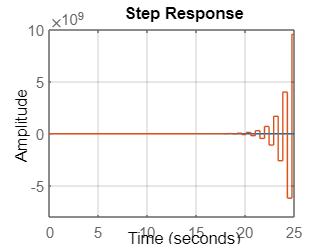

% unstable case
h = h_high;

numEuler = [4*h -(3*h^2+4*h)];
denEuler = [1 (6*h-2) (1-6*h+3*h^2)];
sysEuler = tf(numEuler, denEuler, h);

figure
stepplot(sys,25);
hold on
grid on
stepplot(sysEuler,25);

% Tustin discretization method

h = h_high;

numTustin = [-3*h^2+8*h -6*h^2 -3*h^2-8*h]

numTustin =     3.0818   -1.3086   -4.3903


denTustin = [3*h^2+12*h+4 6*h^2-8 3*h^2-12*h+4]

denTustin =    10.2584   -6.6914   -0.9498


sysTustin = tf(numTustin, denTustin, h)

sysTustin =
 
   3.082 z^2 - 1.309 z - 4.39
  ----------------------------
  10.26 z^2 - 6.691 z - 0.9498
 
Sample time: 0.46701 seconds
Discrete-time transfer function.




figure
stepplot(sys,25)
hold on
grid on
stepplot(sysTustin,25)